clear
n = 15

n = 15


[u, fu, dfu] = fem_p2(n, 0.01);

         0    0.7250    0.9408

    0.9408    0.9972    1.0486

    1.0486    1.0284    1.0610

    1.0610    1.0320    1.0624

    1.0624    1.0324    1.0625

    1.0625    1.0325    1.0625

    1.0625    1.0325    1.0625

    1.0625    1.0325    1.0626

    1.0626    1.0325    1.0625

    1.0625    1.0325    1.0625

    1.0625    1.0325    1.0625

    1.0625    1.0324    1.0624

    1.0624    1.0320    1.0610

    1.0610    1.0284    1.0486

    1.0486    0.9972    0.9408

    0.9408    0.7250         0



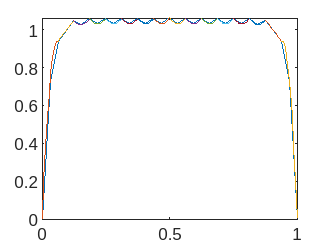



figure
xx = linspace(0, 1, 2*n + 3);
plot(xx, u)
h = 1/(n+1);
hold on
for i = 1:n+1
    a = xx(2*i-1);
    b = xx(2*i+1);
    f = fu{i};
    xcurr = linspace(a, b, 10)';
    ucurr = f(xcurr);
    plot(xcurr, ucurr)
end